# **Visualizing effect size for paired T sing along vs rest**

clear all
% Specify directories and patients
subjects_path='/Volumes/LASA/Aphasia_project/tb-fMRI/code/L2/paired T test/';
data_path='/Volumes/LASA/Aphasia_project/tb-fMRI/data/LASA/';
output_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/effect_size/pairedT/singavssingm/';
derdir='derivatives';
L1dir='SPM_first_level';
L1folder='L1_dur0_explbase_microres72_art_explmask_TU_missed';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/tbfMRI_LASA_current_code/notebooks/effect_size'; %add code path

We will extract the peak values from the coordinates with significant results in the paired T-test and flexible factorial for the corresponding contrasts:

- Paired T, Tydyy-Uulaa Singing along vs singing from memory: PreG R/IFG R (58,4,29)

% Save peak value and contrast name to variable
peak2=[58,4,29]; %paired T singavssingm MNI coord in mm

## Contrast 1: Paired T test Tydyy-Uulaa Sing along vs Rest

cd(subjects_path)
load('subjects_s3')
subjects_s3(ismember({subjects_s3.name}, {'sub-14','sub-30'})) = [];
subjects=subjects_s3;

%Select pair of scans for each group
n=1; a=1;
for sbj = 1:size(subjects, 1)
    disp(subjects(sbj).name)
    if subjects(sbj).group==1
        ses_pre='ses-001'; ses_post='ses-002';
    elseif subjects(sbj).group==2
        ses_pre='ses-002'; ses_post='ses-003';
    end
    sub_path_pre= fullfile(data_path, subjects(sbj).name, ses_pre, derdir,L1dir, L1folder);
    cd(sub_path_pre), load('SPM.mat')
    con_idx_pre=find(ismember({SPM.xCon.name}, {['Sing_along> sing_mem']}));
    if ~isempty(con_idx_pre)
        if con_idx_pre >9
            con_pre{sbj,1}=spm_select('List', fullfile(sub_path_pre),['^con_00' num2str(con_idx_pre) '.*\.nii$']);
        elseif ~isempty(con_idx_pre) && con_idx_pre <10
            con_pre{sbj,1}=spm_select('List', fullfile(sub_path_pre),['^con_000' num2str(con_idx_pre) '.*\.nii$']);
        end
        con_fnames_pre{sbj,1}=fullfile(sub_path_pre, con_pre{sbj,1});
    end
    clear SPM
    sub_path_post= fullfile(data_path, subjects(sbj).name, ses_post, derdir,L1dir,L1folder);
    cd (sub_path_post), load('SPM.mat')
    con_idx_post=find(ismember({SPM.xCon.name}, {['Sing_along> sing_mem']}));
    if ~isempty(con_idx_post)
        if con_idx_post >9
            con_post{sbj,1}=spm_select('List', fullfile(sub_path_post),['^con_00' num2str(con_idx_post) '.*\.nii$']);
        elseif con_idx_post <10
            con_post{sbj,1}=spm_select('List', fullfile(sub_path_post),['^con_000' num2str(con_idx_post) '.*\.nii$']);
        end
        con_fnames_post{sbj,1}=fullfile(sub_path_post, con_post{sbj,1});
    end
    clear SPM
end

sub-01
sub-02
sub-05
sub-06
sub-07
sub-08
sub-09
sub-10
sub-11
sub-13
sub-16
sub-20
sub-21
sub-22
sub-23
sub-25
sub-26
sub-29


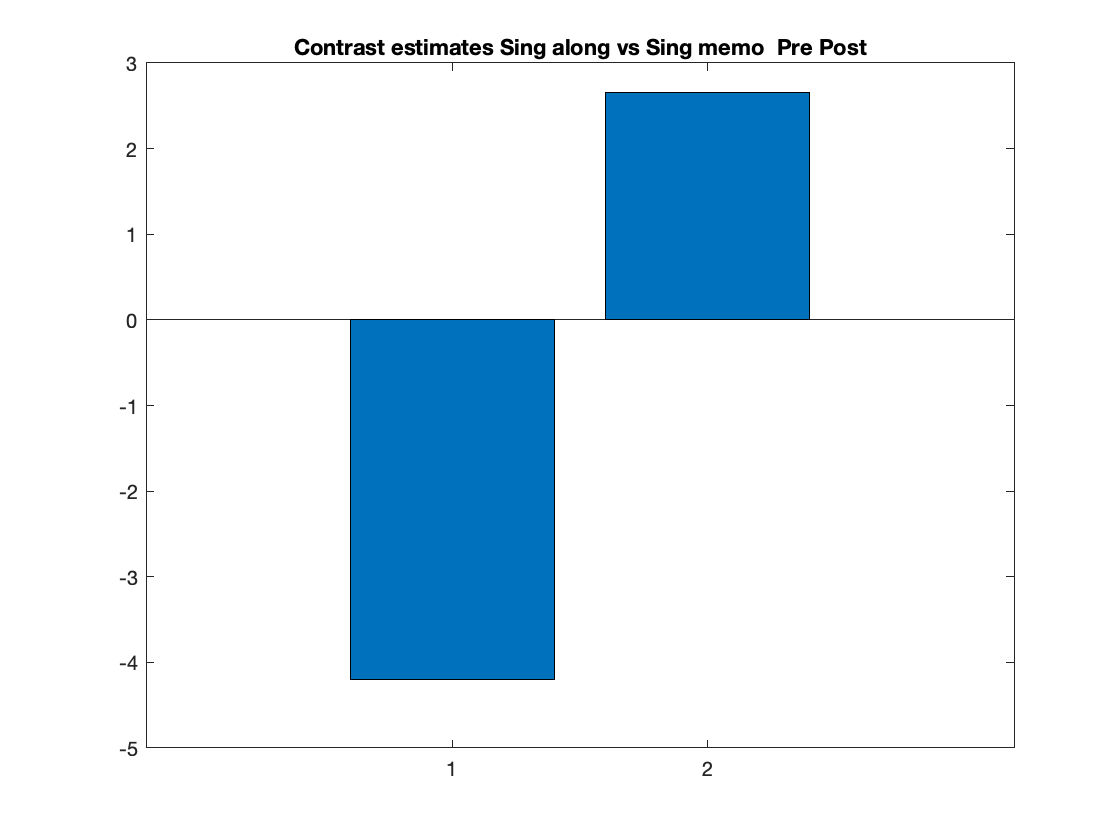



% Get contrast estimate value at the peak for all patients pre
for i=1:size(con_fnames_pre,1)    
    V=spm_vol(con_fnames_pre{i}); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak2(1,1) & XYZmm(2,:)==peak2(1,2) & XYZmm(3,:)==peak2(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(con_fnames_pre{i});
    pa_int_peak_pre{i,1}=str2num(subjects(i).name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak_pre{i,2}=int;% Save intensity value for the peak from all patients
end

% Get contrast estimate value at the peak for all patients pre
for j=1:size(con_fnames_post,1)    
    V=spm_vol(con_fnames_post{j}); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    idx=find(XYZmm(1,:)==peak2(1,1) & XYZmm(2,:)==peak2(1,2) & XYZmm(3,:)==peak2(1,3)); %Get the intensity value for the peak
    XYZmm(:,idx);
    [Xvox, Yvox, Zvox]=ind2sub(size(Y(:,:,:,1)),idx);
    int=Y(Xvox,Yvox,Zvox,:);
    [~,name,ext] =fileparts(con_fnames_post{j});
    pa_int_peak_post{j,1}=str2num(subjects(j).name(end-1:end)); %Save the patient ID in BIDS
    pa_int_peak_post{j,2}=int;% Save intensity value for the peak from all patients
end

%% Plot Contrast Estimate at the Peak Value Pre Post 
        figure
        pre=mean(cell2mat(pa_int_peak_pre(:,2)));
        post=mean(cell2mat(pa_int_peak_post(:,2)));
        bar([pre;post])
        title (['Contrast estimates Sing along vs Sing memo  Pre Post'])
        cd(output_path)
        saveas(gcf,['ContrastEstimates_Singavssingmemo_pre_post.jpg'])

        save('ContrastEstimates_singavssingmemo_pre_post','pa_int_peak_pre','pa_int_peak_post')
        ContEst_singavssingmemo_T=table(pa_int_peak_pre,pa_int_peak_post);
        writetable(ContEst_singavssingmemo_T, 'ContEst_singavssingmemo_T.xlsx')
